% 6 - b)
clear, clc, close all;

syms a b c
eq1 = 1e4*a + 1e3*b + 10e2*c == 1

$$eq1 = 10000\,a+1000\,b+1000\,c=1$$

eq2 = 5*1e2*a + 4*10*b + 3*c ==0

$$eq2 = 500\,a+40\,b+3\,c=0$$

eq3 = 20*1e2*a + 12*10*b + 6*c == 0

$$eq3 = 2000\,a+120\,b+6\,c=0$$


[A,B] = equationsToMatrix([eq1, eq2, eq3], [a,b,c])

$$A = \left(\begin{array}{ccc} 10000 & 1000 & 1000\\ 500 & 40 & 3\\ 2000 & 120 & 6 \end{array}\right)$$

$$B = \left(\begin{array}{c} 1\\ 0\\ 0 \end{array}\right)$$

X = linsolve(A,B)

$$X = \left(\begin{array}{c} \frac{3}{455000}\\ -\frac{3}{18200}\\ \frac{1}{910} \end{array}\right)$$


syms x y
fx = @(t) X(1)*t.^5 + X(2)*t.^4 + X(3)*t.^3 + 0*t.^2 + 0*t + 0

fx = 다음 값을 갖는 function_handle :
    @(t)X(1)*t.^5+X(2)*t.^4+X(3)*t.^3+0*t.^2+0*t+0


fy = @(t) X(1)*t.^5 + X(2)*t.^4 + X(3)*t.^3 + 0*t.^2 + 0*t + 0

fy = 다음 값을 갖는 function_handle :
    @(t)X(1)*t.^5+X(2)*t.^4+X(3)*t.^3+0*t.^2+0*t+0


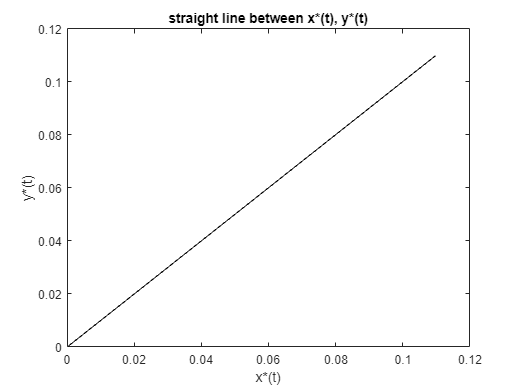


lim = [0:1:10];
plot(fx(lim), fy(lim), 'k')
title('straight line between x*(t), y*(t)')
xlabel('x*(t)')
ylabel('y*(t)')

## 6 - c)

% 6 - c)
clear, clc, close all;

syms a b c
eq1 = 1e4*a + 1e3*b + 10e2*c == 1

$$eq1 = 10000\,a+1000\,b+1000\,c=1$$

eq2 = 5*1e2*a + 4*10*b + 3*c ==0

$$eq2 = 500\,a+40\,b+3\,c=0$$

eq3 = 20*1e2*a + 12*10*b + 6*c == 0

$$eq3 = 2000\,a+120\,b+6\,c=0$$


[A,B] = equationsToMatrix([eq1, eq2, eq3], [a,b,c])

$$A = \left(\begin{array}{ccc} 10000 & 1000 & 1000\\ 500 & 40 & 3\\ 2000 & 120 & 6 \end{array}\right)$$

$$B = \left(\begin{array}{c} 1\\ 0\\ 0 \end{array}\right)$$

X = linsolve(A,B)

$$X = \left(\begin{array}{c} \frac{3}{455000}\\ -\frac{3}{18200}\\ \frac{1}{910} \end{array}\right)$$


syms x y t
fx = @(t) X(1)*t.^5 + X(2)*t.^4 + X(3)*t.^3 + 0*t.^2 + 0*t + 0

fx = 다음 값을 갖는 function_handle :
    @(t)X(1)*t.^5+X(2)*t.^4+X(3)*t.^3+0*t.^2+0*t+0


fy = @(t) X(1)*t.^5 + X(2)*t.^4 + X(3)*t.^3 + 0*t.^2 + 0*t + 0

fy = 다음 값을 갖는 function_handle :
    @(t)X(1)*t.^5+X(2)*t.^4+X(3)*t.^3+0*t.^2+0*t+0


fxdt = @(t) 5*X(1)*t.^4 + 4*X(2)*t.^3 + 3*X(3)*t.^2 + 2*0*t.^1 + 0

fxdt = 다음 값을 갖는 function_handle :
    @(t)5*X(1)*t.^4+4*X(2)*t.^3+3*X(3)*t.^2+2*0*t.^1+0


fydt = @(t) 5*X(1)*t.^4 + 4*X(2)*t.^3 + 3*X(3)*t.^2 + 2*0*t.^1 + 0

fydt = 다음 값을 갖는 function_handle :
    @(t)5*X(1)*t.^4+4*X(2)*t.^3+3*X(3)*t.^2+2*0*t.^1+0



lim = [0:0.1:10];
xdot2 = fxdt(lim).^2;
ydot2 = fydt(lim).^2;
v = sqrt(xdot2+ydot2)

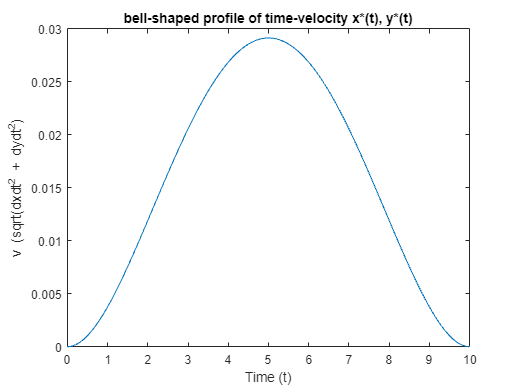


plot(lim, v)
title('bell-shaped profile of time-velocity x*(t), y*(t)')
xlabel('Time (t)')
ylabel('v (sqrt(dxdt^2 + dydt^2)')